# SLCO4A - Aula Prática 2

## Plot com o MATLAB

### Plotando em duas dimensões

a) Plot a função $y\left(x\right)=x^2$, $-2\le x\le 2$

clear all; close all
clc
x0=-2:2

x0 =     -2    -1     0     1     2


length(x0)

ans = 5

y0=x0.^2;
length(y0)

ans = 5

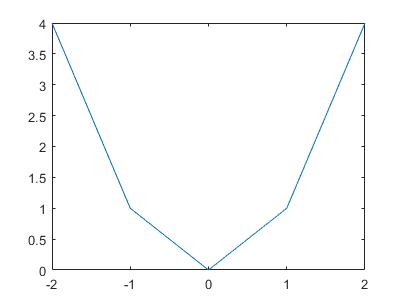

plot(x0,y0)

**Observação 1:** Note que a representação gráfica correspondeu a uma quantidade de cinco pares ordenados (x,y), que resultou em um gráfico distorcido da representação desejada para a função. Neste tipo de caso deve ser aumentar o número de pontos da variável independente para obter uma melhor representação gráfica.

b) Aumente o número de ponto da variável independente $x$, considerando passo de incremento de $0\ldotp 1$e refaça o item anterior

x=-2:0.1:2

x =    -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y=x.^2

y =     4.0000    3.6100    3.2400    2.8900    2.5600    2.2500    1.9600    1.6900    1.4400    1.2100    1.0000    0.8100    0.6400    0.4900    0.3600    0.2500    0.1600    0.0900    0.0400    0.0100         0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000


length(y)

ans = 41

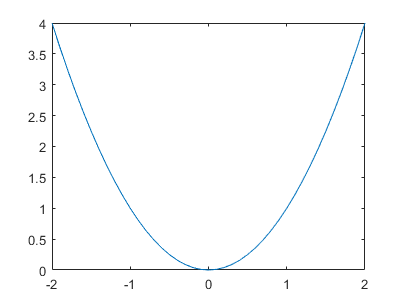

plot(x,y)

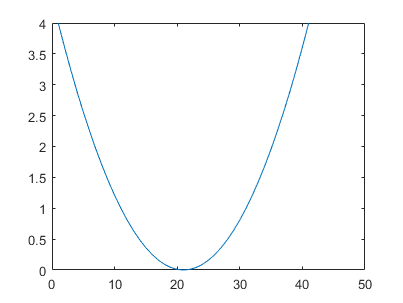

plot(y)

y=x.^2;
length(y)

ans = 41

**Observação 2:** Há algumas opções disponíveis no canto superior direito das figuras. As opções permitem  exportar, visualizar valor numérico, dar zoom e editar em janela gráfica externa.  

### Comando `linspace` e `logspace`

x=0:0.25:1

x =          0    0.2500    0.5000    0.7500    1.0000


x=linspace(0,1,5)

x =          0    0.2500    0.5000    0.7500    1.0000


%Criar umv etor com cinco pontos espaçados logaritmicamente entre 10^0 até
%10^1
logspace(0,1,5)

ans =     1.0000    1.7783    3.1623    5.6234   10.0000


### Plotando várias funções em uma figura

c) Plot as seguintes funções em uma mesma figura.$y\left(x\right)=x^2 \cos \left(x\right)$, $g\left(x\right)=\textrm{xcos}\left(x\right)$ e $f\left(x\right)=2^x \textrm{sen}\left(x\right)$, $0\le x\le 2\pi$, considerando 100 pontos.

x=linspace(0,2*pi,100)

x =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


y=(x.^2).*cos(x)

y =          0    0.0040    0.0160    0.0356    0.0624    0.0957    0.1346    0.1782    0.2253    0.2745    0.3244    0.3734    0.4198    0.4619    0.4978    0.5257    0.5437    0.5498    0.5421    0.5190    0.4784    0.4188    0.3385    0.2362    0.1104   -0.0399   -0.2158   -0.4179   -0.6468   -0.9027   -1.1857   -1.4955   -1.8316   -2.1932   -2.5793   -2.9883   -3.4186   -3.8682   -4.3348   -4.8158   -5.3084   -5.8095   -6.3155   -6.8230   -7.3279   -7.8263   -8.3138   -8.7861   -9.2385   -9.6664


g=x.*cos(x)

g =          0    0.0633    0.1259    0.1870    0.2457    0.3015    0.3535    0.4011    0.4437    0.4805    0.5111    0.5348    0.5512    0.5598    0.5603    0.5522    0.5354    0.5095    0.4746    0.4304    0.3769    0.3142    0.2425    0.1618    0.0725   -0.0252   -0.1308   -0.2439   -0.3640   -0.4905   -0.6227   -0.7601   -0.9019   -1.0472   -1.1953   -1.3453   -1.4962   -1.6472   -1.7974   -1.9456   -2.0910   -2.2326   -2.3693   -2.5001   -2.6241   -2.7403   -2.8477   -2.9455   -3.0326   -3.1083


f=(2.^x).*sin(x)

f =          0    0.0663    0.1382    0.2160    0.2995    0.3888    0.4839    0.5848    0.6913    0.8033    0.9205    1.0429    1.1699    1.3014    1.4369    1.5758    1.7178    1.8620    2.0080    2.1548    2.3018    2.4479    2.5922    2.7336    2.8710    3.0032    3.1287    3.2464    3.3546    3.4519    3.5366    3.6071    3.6616    3.6983    3.7154    3.7108    3.6827    3.6291    3.5480    3.4372    3.2949    3.1190    2.9074    2.6583    2.3697    2.0397    1.6668    1.2491    0.7853    0.2739


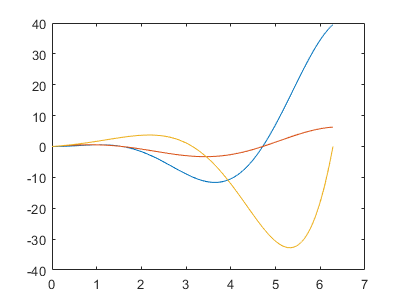

plot(x,y,x,g,x,f)

**Observação 3:** Note que a figura foi criada com cores predefinidas e linha do tipo sólido. É possível criar gráficos usando cores, símbolos e tipos de linhas personalizados por meio da inserção de outros argumentos na função `plot`, vide opções por meio do comando `help plot.`

### Configurando opções do plot

d) Plot as funções $y_1 \left(x\right)=\textrm{asin}\left(x\right)$e $y_2 \left(x\right)=\textrm{acos}\left(x\right)$, $-1\le x\le 1$ com 15 elementos. Para a primeira função utilize cor preta, linha pontilhada e marcadores do tipo pentagrama. Enquanto que para segunda função utilize cor vermelha, linha tracejada e marcadores do tipo círculo.  

x=linspace(-1,1,15)

x =    -1.0000   -0.8571   -0.7143   -0.5714   -0.4286   -0.2857   -0.1429         0    0.1429    0.2857    0.4286    0.5714    0.7143    0.8571    1.0000


y1=asin(x)

y1 =    -1.5708   -1.0297   -0.7956   -0.6082   -0.4429   -0.2898   -0.1433         0    0.1433    0.2898    0.4429    0.6082    0.7956    1.0297    1.5708


y2=acos(x)

y2 =     3.1416    2.6005    2.3664    2.1790    2.0137    1.8605    1.7141    1.5708    1.4274    1.2810    1.1279    0.9626    0.7752    0.5411         0


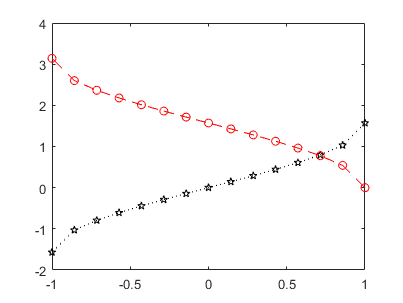

plot(x,y1,'k:p',x,y2,'r--o')

Outra forma de sintaxe para o comando `plot` que especifica cor e tipo de linha é da seguinte forma

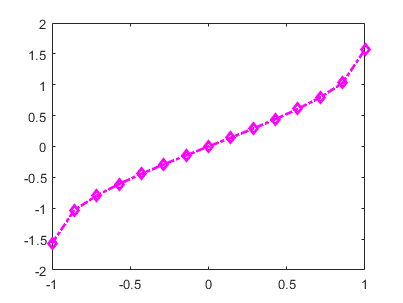

plot(x,y1,'Color',[1,0,1],'LineWidth',2,"Marker","diamond","Linestyle","-.")

### Comando `hold`

Ao repetir a execução do comando `plot` para uma figura prévia, a representação gráfica obtida anteriormente é descartada. Para manter o gráfico anterior e acrescentar um novo gráfico por meio da repetição do comando `plot` deve-se utilizar o comando `hold on. `Veja o exemplo

x=linspace(0,2*pi,150)

x =          0    0.0422    0.0843    0.1265    0.1687    0.2108    0.2530    0.2952    0.3374    0.3795    0.4217    0.4639    0.5060    0.5482    0.5904    0.6325    0.6747    0.7169    0.7590    0.8012    0.8434    0.8855    0.9277    0.9699    1.0121    1.0542    1.0964    1.1386    1.1807    1.2229    1.2651    1.3072    1.3494    1.3916    1.4337    1.4759    1.5181    1.5603    1.6024    1.6446    1.6868    1.7289    1.7711    1.8133    1.8554    1.8976    1.9398    1.9819    2.0241    2.0663


plot(x,cos(x))
hold on
plot(x,sin(x))

### Formatando uma figura

Há alguns comandos úteis para formatação de figuras, tais como: 

`grid-title-xlabel-ylabel-legend-text-gtext-axis-xlim–ylim`

x=linspace(0,2*pi,150)

x =          0    0.0422    0.0843    0.1265    0.1687    0.2108    0.2530    0.2952    0.3374    0.3795    0.4217    0.4639    0.5060    0.5482    0.5904    0.6325    0.6747    0.7169    0.7590    0.8012    0.8434    0.8855    0.9277    0.9699    1.0121    1.0542    1.0964    1.1386    1.1807    1.2229    1.2651    1.3072    1.3494    1.3916    1.4337    1.4759    1.5181    1.5603    1.6024    1.6446    1.6868    1.7289    1.7711    1.8133    1.8554    1.8976    1.9398    1.9819    2.0241    2.0663


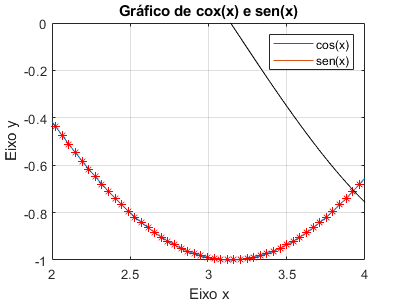

plot(x,cos(x),'r*',x,sin(x),'k')
legend('cos(x)','sen(x)')
grid
xlabel('Eixo x')
ylabel('Eixo y')
title('Gráfico de cox(x) e sen(x)')
text(3,0.3,'sen(x)')
text(2,0.3,'cos(x)')
axis([2,4,-1,0])

### Plotando em diferentes figuras

Para criar diferentes figuras pode-se especificar a partir do comando `figure(1) ... figure(k) `e utilizar para cada figura o comando `plot.`

Mas também é possível criar múltiplas figuras dentro de uma única figura por meio do comando `subplot(m,n,p). `Com este comando cria-se dentro de uma mesma janela de figura que estará dividida em `mxn` pequenas subfiguras.

e) Utilizando o comando `subplot` plot as seguintes funções $f\left(x\right)=\cos \left(x\right)$, $g\left(x\right)=e^{-\frac{x}{2\pi }} \cos \left(x\right)$, $f\left(x\right)=e^{\frac{x}{2\pi }} \cos \left(x\right)$ em uma única figura contendo 3 subfiguras disposta em um arranjo 3x1

figure
x=0:0.1:4*pi

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


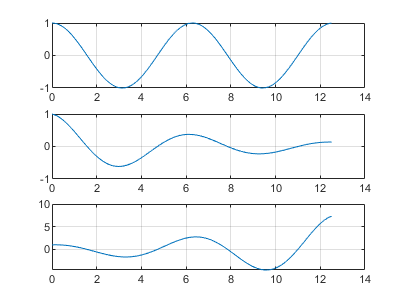

subplot(3,1,1)
plot(x,cos(x))
grid on
subplot(3,1,2)
plot(x,exp(-x/(2*pi)).*cos(x))
grid on
subplot(3,1,3)
plot(x,exp(x/(2*pi)).*cos(x))
grid on

### `Funções por partes`

f) Obtenha a representação gráfica de uma função definida por partes, tal que

t1=-2:0.01:2

t1 =    -2.0000   -1.9900   -1.9800   -1.9700   -1.9600   -1.9500   -1.9400   -1.9300   -1.9200   -1.9100   -1.9000   -1.8900   -1.8800   -1.8700   -1.8600   -1.8500   -1.8400   -1.8300   -1.8200   -1.8100   -1.8000   -1.7900   -1.7800   -1.7700   -1.7600   -1.7500   -1.7400   -1.7300   -1.7200   -1.7100   -1.7000   -1.6900   -1.6800   -1.6700   -1.6600   -1.6500   -1.6400   -1.6300   -1.6200   -1.6100   -1.6000   -1.5900   -1.5800   -1.5700   -1.5600   -1.5500   -1.5400   -1.5300   -1.5200   -1.5100


t2=2.01:0.01:4.99

t2 =     2.0100    2.0200    2.0300    2.0400    2.0500    2.0600    2.0700    2.0800    2.0900    2.1000    2.1100    2.1200    2.1300    2.1400    2.1500    2.1600    2.1700    2.1800    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900    2.5000


t3=5:0.01:8

t3 =     5.0000    5.0100    5.0200    5.0300    5.0400    5.0500    5.0600    5.0700    5.0800    5.0900    5.1000    5.1100    5.1200    5.1300    5.1400    5.1500    5.1600    5.1700    5.1800    5.1900    5.2000    5.2100    5.2200    5.2300    5.2400    5.2500    5.2600    5.2700    5.2800    5.2900    5.3000    5.3100    5.3200    5.3300    5.3400    5.3500    5.3600    5.3700    5.3800    5.3900    5.4000    5.4100    5.4200    5.4300    5.4400    5.4500    5.4600    5.4700    5.4800    5.4900


f1=ones(size(t1))

f1 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


f2=zeros(size(t2))

f2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


f3=t3.*sin(4*pi*t3)

f3 =    -0.0000    0.6279    1.2484    1.8517    2.4280    2.9683    3.4638    3.9065    4.2892    4.6056    4.8504    5.0195    5.1099    5.1199    5.0490    4.8979    4.6689    4.3652    3.9913    3.5528    3.0565    2.5099    1.9216    1.3006    0.6567   -0.0000   -0.6593   -1.3106   -1.9437   -2.5485   -3.1153   -3.6349   -4.0991   -4.5003   -4.8318   -5.0882   -5.2651   -5.3594   -5.3694   -5.2945   -5.1357   -4.8951   -4.5763   -4.1839   -3.7239   -3.2034   -2.6304   -2.0136   -1.3628   -0.6881


t=[t1 t2 t3]

t =    -2.0000   -1.9900   -1.9800   -1.9700   -1.9600   -1.9500   -1.9400   -1.9300   -1.9200   -1.9100   -1.9000   -1.8900   -1.8800   -1.8700   -1.8600   -1.8500   -1.8400   -1.8300   -1.8200   -1.8100   -1.8000   -1.7900   -1.7800   -1.7700   -1.7600   -1.7500   -1.7400   -1.7300   -1.7200   -1.7100   -1.7000   -1.6900   -1.6800   -1.6700   -1.6600   -1.6500   -1.6400   -1.6300   -1.6200   -1.6100   -1.6000   -1.5900   -1.5800   -1.5700   -1.5600   -1.5500   -1.5400   -1.5300   -1.5200   -1.5100


f=[f1 f2 f3]

f =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


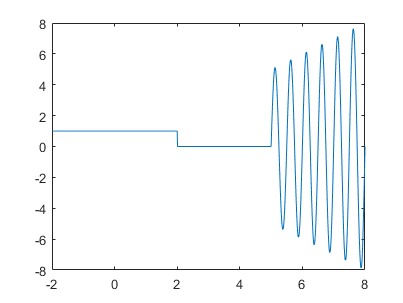

figure
plot(t,f)

## `Outros comandos para plotar uma função`

Além do comando `plot `há outros comandos que podem ser empregados para obter uma representação gráfica de uma função, tais como:

`loglog-semilogx-semilogy-area-fplot-ezplot`

f) Considere a função $y\left(x\right)=2x+30$, $1\le x\le 1000$. Obtenha diferentes representações gráficas utilizando outros comandos além do `plot.`

x=1:1000

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y=2*x+30

y =     32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100   102   104   106   108   110   112   114   116   118   120   122   124   126   128   130


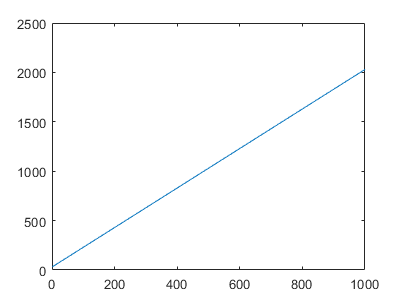

figure
plot(x,y)

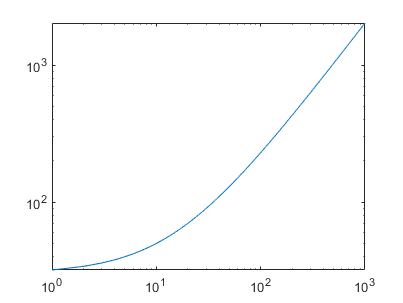

figure
loglog(x,y)

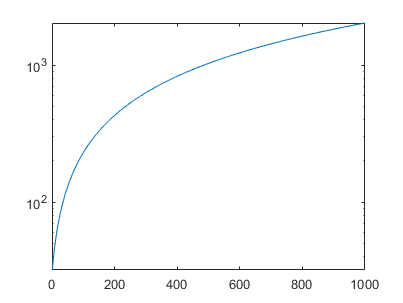

figure
semilogy(x,y)

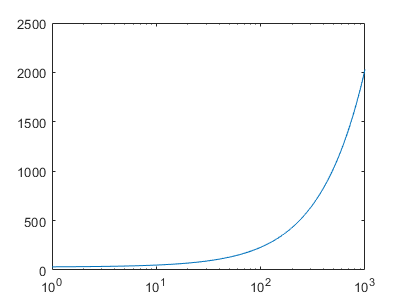

figure
semilogx(x,y)

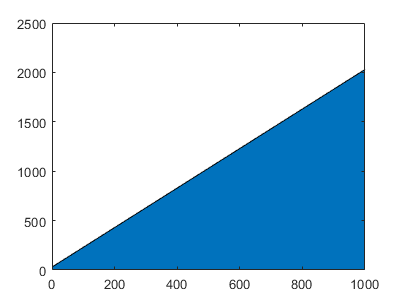

figure
area(x,y)

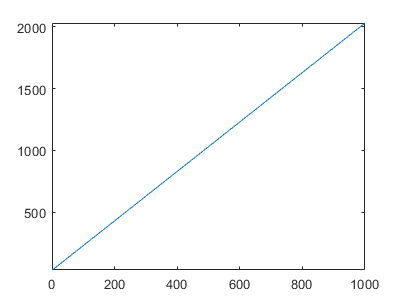

figure
fplot(@(x)2.*x+30,[1,1000])

%fplot('2*x+30',[1,1000])
%ezplot('2*x+30',[1,1000])

### Plot de funções de tempo discreto

g) Considere a função de tempo discreto $f\left(k\right)=k^2$, $k\in Z:-3\le k\le \;3$.

k=-3:3

k =     -3    -2    -1     0     1     2     3


f=k.^2

f =      9     4     1     0     1     4     9


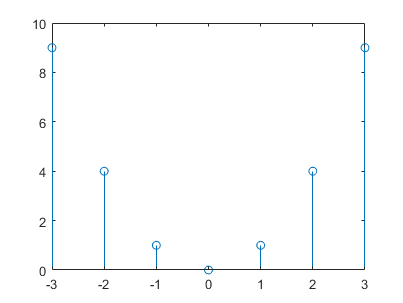

stem(k,f)

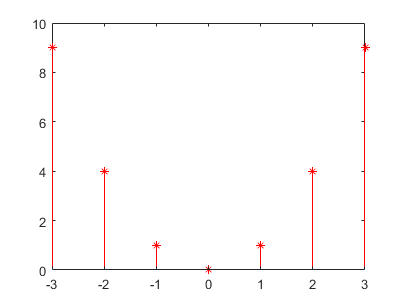

stem(k,f,'r*')

### Gráfico em coordenadas polares

theta = linspace(0,4*pi,50)

theta =          0    0.2565    0.5129    0.7694    1.0258    1.2823    1.5387    1.7952    2.0517    2.3081    2.5646    2.8210    3.0775    3.3339    3.5904    3.8468    4.1033    4.3598    4.6162    4.8727    5.1291    5.3856    5.6420    5.8985    6.1550    6.4114    6.6679    6.9243    7.1808    7.4372    7.6937    7.9502    8.2066    8.4631    8.7195    8.9760    9.2324    9.4889    9.7453   10.0018   10.2583   10.5147   10.7712   11.0276   11.2841   11.5405   11.7970   12.0535   12.3099   12.5664


c=theta

c =          0    0.2565    0.5129    0.7694    1.0258    1.2823    1.5387    1.7952    2.0517    2.3081    2.5646    2.8210    3.0775    3.3339    3.5904    3.8468    4.1033    4.3598    4.6162    4.8727    5.1291    5.3856    5.6420    5.8985    6.1550    6.4114    6.6679    6.9243    7.1808    7.4372    7.6937    7.9502    8.2066    8.4631    8.7195    8.9760    9.2324    9.4889    9.7453   10.0018   10.2583   10.5147   10.7712   11.0276   11.2841   11.5405   11.7970   12.0535   12.3099   12.5664


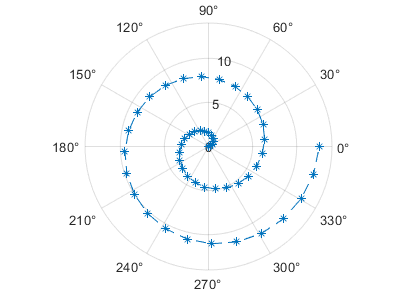

polarplot(theta,c,'--*')

### Gráfico tridimensional

x=0:.1:100

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y=cos(x)

y =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


z=sin(x)

z =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


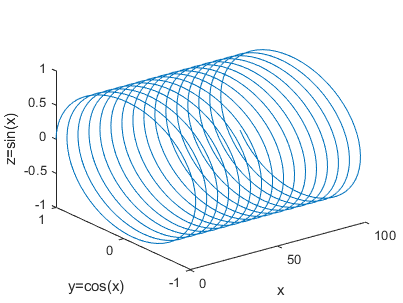

plot3(x,y,z)
xlabel('x')
ylabel('y=cos(x)')
zlabel('z=sin(x)')